I = imread("img\bob.JPG")

I = 1920×2560×3 uint8 array
I(:,:,1) =

   146   148   145   145   147   146   146   144   145   147   146   148   147   145   143   144   148   146   144   146   142   142   145   144   148   151   147   142   143   143   143   146   138   141   145   144   145   148   144   143   147   147   153   156   146   142   143   148   149   149   147   146   146   145   148   147   147   145   145   145   146   148   151   150   149   149   148   149   151   149   148   149   150   150   150   152   150   147   148   149   146   148   147   147   147   148   149   149   148   149   149   149   149   149   147   146   148   147   148   147   148   148   149   149   148   146   146   146   148   147   147   147   146   145   147   146   146   145   145   148   147   141   143   147   147   147   146   144   147   149   148   148   147   145   145   143   146   149   149   147   147   147   148   148   147   146   147   145   145   143   146   148   148   149   156   152   148   146   144   148

I_r = zeros(size(I,1),size(I,2),size(I,3));
I_r(:,:,1) = I(:,:,1);
I_g = zeros(size(I,1),size(I,2),size(I,3));
I_g(:,:,2) = I(:,:,2);
I_b = zeros(size(I,1),size(I,2),size(I,3));
I_b(:,:,3) = I(:,:,3);



imshow(I)

imshow(I_r/255)%Red

imshow(I_g/255)%Gree

imshow(I_b/255)%Blue

threshold = 0.5;
I_r_thres = 1.*(I_r/255>threshold);
imshow((I_r_thres))%Red
imshow((I_r_thres(:,:,1)))%Red(B/W)
I_g_thres = 1.*(I_g/255>threshold);
imshow((I_g_thres))%Green
imshow((I_g_thres(:,:,2)))%Green(B/W)
I_b_thres = 1.*(I_b/255>threshold);
imshow((I_b_thres))%Blue
imshow((I_b_thres(:,:,3)))%Blue(B/W)
imshow(I_r_thres + I_b_thres + I_g_thres)

imshow(maskedRGBImage(:,:,1))
I_n = I;
 
mask_p = uint8(maskedRGBImage(:,:,2) >= 50);
mask_n = uint8(maskedRGBImage(:,:,2) < 50);

I_n = I_n.*mask_n;
for i = 1:3
    I_n(:,:,mod(i,3)+1) = I_n(:,:,mod(i,3)+1) + maskedRGBImage(:,:,mod(i-1,3)+1).*mask_p;
end
imshow(I_n)


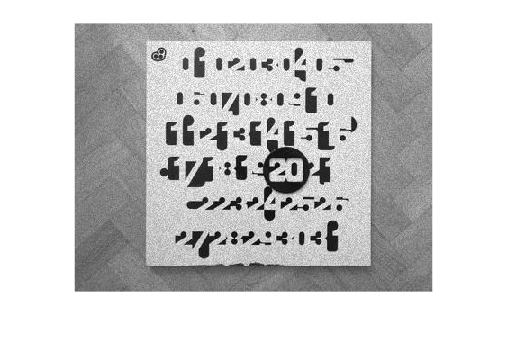

C = imread("img\calendar_speckle10.jpg");
C = im2double(C);
imshow(C)



s = fspecial("sobel");
g = fspecial("gaussian");
tic
for i = 1:1000
    A = conv2(conv2(C,s),g);
end
toc

Elapsed time is 5.122166 seconds.


tic
for i = 1:1000
    B = conv2(C,conv2(s,g));
end
toc

Elapsed time is 2.517205 seconds.


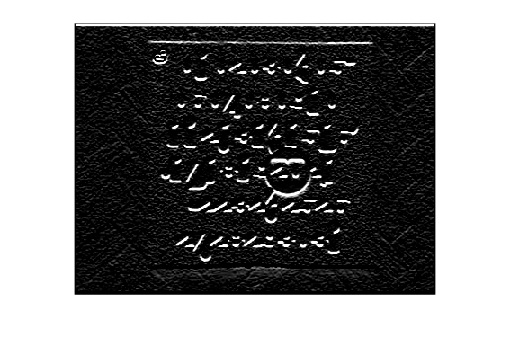

imshow(A)

imshow(B)

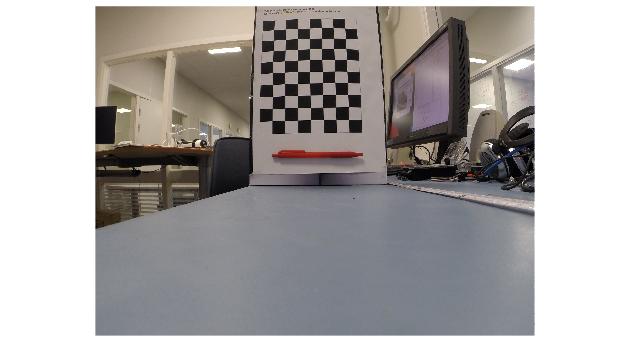

Pen1 = imread("img\pen1.JPG");
Pen2 = imread("img\pen2.JPG");
imshow(Pen1)

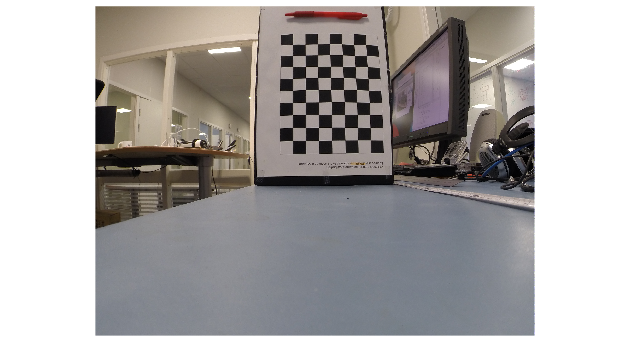

imshow(Pen2)


Pen1_len = 1563 - 1031

Pen1_len = 532

Pen2_len = 1588 - 1105

Pen2_len = 483

square_size1 = (1556 - 960)/8

square_size1 = 74.5000

square_size2 = (1642 - 1086)/8

square_size2 = 69.5000


distorted_pen1_len = 20*Pen1_len/square_size1

distorted_pen1_len = 142.8188

distorted_pen2_len = 20*Pen2_len/square_size2

distorted_pen2_len = 138.9928


f = 199;

z1 = f*distorted_pen1_len/140

z1 = 203.0067

z2 = f*distorted_pen2_len/140

z2 = 197.5683

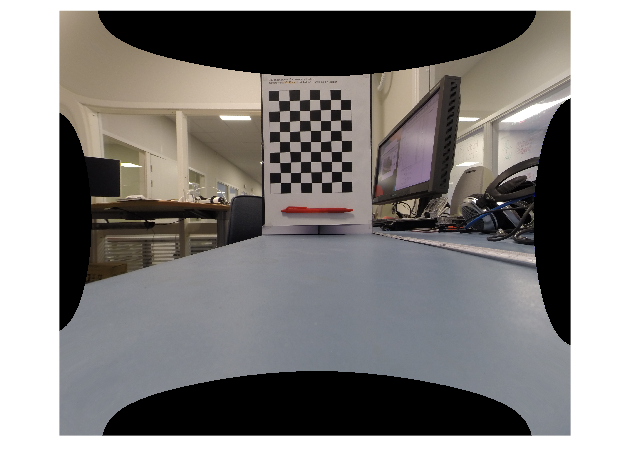


imshow(undistortImage(Pen1,cameraParams,'OutputView','full'))

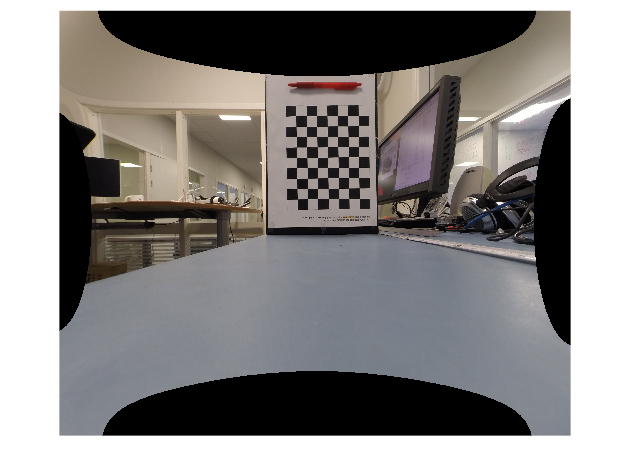

imshow(undistortImage(Pen2,cameraParams,'OutputView','full'))

Pen1_len = 2178 - 1643

Pen1_len = 535

Pen2_len = 2237 - 1692

Pen2_len = 545


square_size1 = (2169 - 1565)/8

square_size1 = 75.5000

square_size2 = (2296 - 1683)/8

square_size2 = 76.6250


undistorted_pen1_len = 20*Pen1_len/square_size1

undistorted_pen1_len = 141.7219

undistorted_pen2_len = 20*Pen2_len/square_size2

undistorted_pen2_len = 142.2512



z3 = f*undistorted_pen1_len/140

z3 = 201.4475

z4 = f*undistorted_pen2_len/140

z4 = 202.2000